% =-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=
% Communication Systems
% Computer Assignment 2 : Amplitude Modulation
% Mohammad Mahdi Abdolhosseini
% Student Number: 810 198 434
% Fall 2021
% =-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=
clc; clear; close all;

# **% Part 1:**

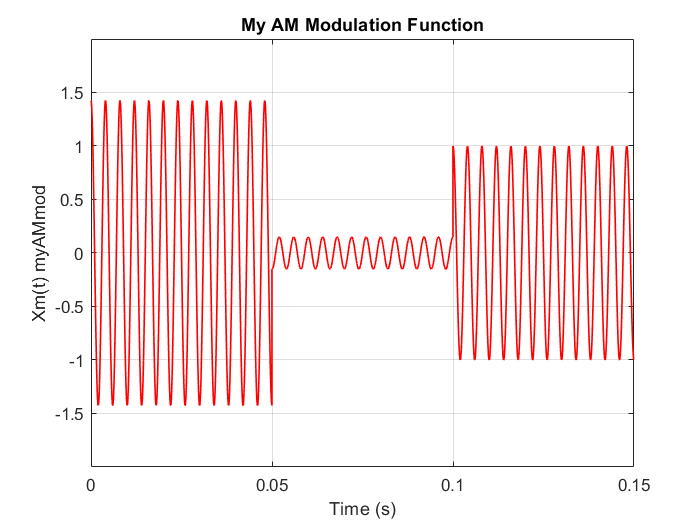

fs_part1 = 100000; % 100kHz
t0_part1 = 0.15;
ts_part1 = 1/fs_part1;
t = 0:ts_part1:t0_part1 - ts_part1;
Xmt = zeros([1,t0_part1*fs_part1]);
Xmt(1, 1:(t0_part1*fs_part1/3 - 1)) = 1;
Xmt(1, (t0_part1*fs_part1/3):(t0_part1*fs_part1*2/3 - 1)) = -2;

Ac_part1 = 1;
mu_part1 = 0.85;
fc_part1 = 250;

Xm_myAMmod = my_AMmod(Xmt, Ac_part1, mu_part1, fc_part1, t);
plot(t, Xm_myAMmod, 'r', 'linewidth', 1);
title('My AM Modulation Function');
xlabel('Time (s)');
ylabel('Xm(t) myAMmod');
set(gca,'xtick', 0 : 0.05 : 0.15, 'xlim', [0,0.15]);
set(gca,'ytick', -1.5 : 0.5 : 1.5, 'ylim', [-2,2]);
grid on;

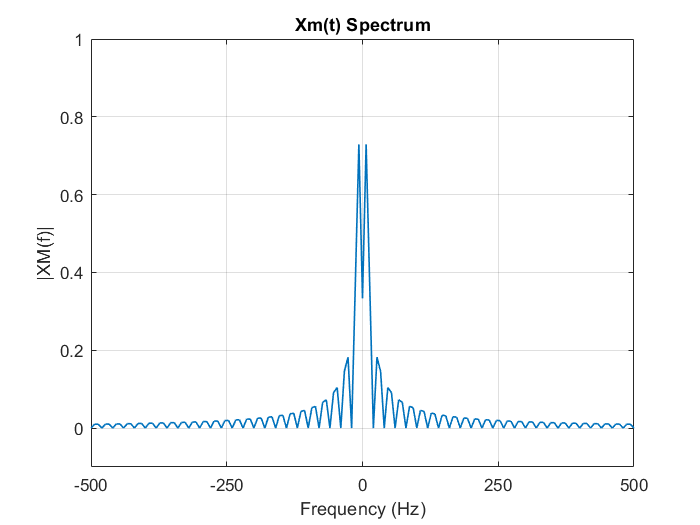


Xmf = fftshift(fft(Xmt));
l_Xmf = length(Xmf);
abs_Xmf = abs(Xmf/l_Xmf);
f1_part1 = -fs_part1/2 : fs_part1/l_Xmf : fs_part1/2 - fs_part1/l_Xmf;
plot(f1_part1, abs_Xmf, 'linewidth', 1);
title('Xm(t) Spectrum');
xlabel('Frequency (Hz)');
ylabel('|XM(f)|');
set(gca,'xtick', -500 : 250 : 500, 'xlim', [-500,500]);
set(gca,'ytick', -1 : 0.2 : 1, 'ylim', [-0.1,1]);
grid on;

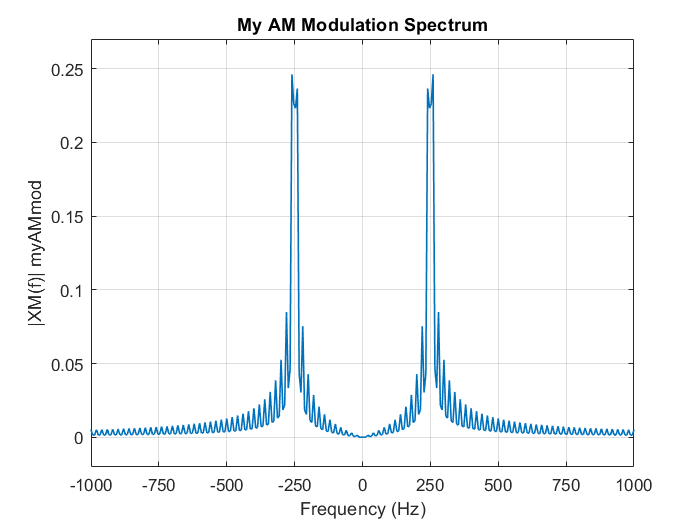


Xmf_myAMmod = fftshift(fft(Xm_myAMmod));
l_Xmf_myAMmod = length(Xmf_myAMmod);
abs_Xmf_myAMmod = abs(Xmf_myAMmod/l_Xmf_myAMmod);
f2_part1 = -fs_part1/2 : fs_part1/l_Xmf_myAMmod : fs_part1/2 - fs_part1/l_Xmf_myAMmod;
plot(f2_part1, abs_Xmf_myAMmod, 'linewidth', 1);
title('My AM Modulation Spectrum');
xlabel('Frequency (Hz)');
ylabel('|XM(f)| myAMmod');
set(gca,'xtick', -1000 : 250 : 1000, 'xlim', [-1000,1000]);
set(gca,'ytick', -0 : 0.05 : 0.25, 'ylim', [-0.02,0.27]);
grid on;

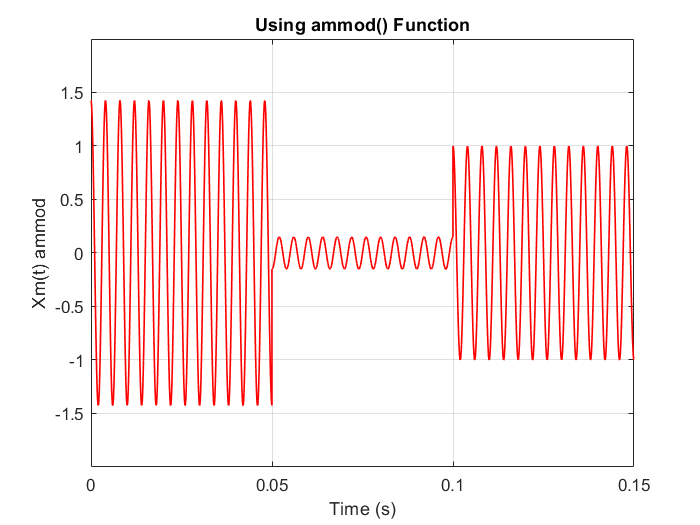


Xmt_in = mu_part1 * Xmt / max(abs(Xmt));
Xm_ammod = ammod(Xmt_in, fc_part1, fs_part1, 0, 1);
plot(t, Xm_ammod, 'r', 'linewidth', 1);
title('Using ammod() Function');
xlabel('Time (s)');
ylabel('Xm(t) ammod');
set(gca,'xtick', 0 : 0.05 : 0.15, 'xlim', [0,0.15]);
set(gca,'ytick', -1.5 : 0.5 : 1.5, 'ylim', [-2,2]);
grid on;

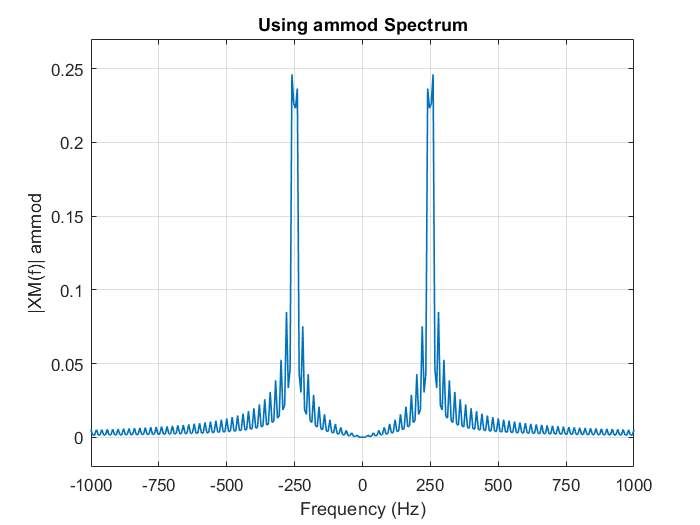




Xmf_ammod = fftshift(fft(Xm_ammod));
l_Xmf_ammod = length(Xmf_ammod);
abs_Xmf_ammod = abs(Xmf_ammod/l_Xmf_ammod);
f3_part1 = -fs_part1/2 : fs_part1/l_Xmf_ammod : fs_part1/2 - fs_part1/l_Xmf_ammod;
plot(f3_part1, abs_Xmf_ammod, 'linewidth', 1);
title('Using ammod Spectrum');
xlabel('Frequency (Hz)');
ylabel('|XM(f)| ammod');
set(gca,'xtick', -1000 : 250 : 1000, 'xlim', [-1000,1000]);
set(gca,'ytick', 0 : 0.05 : 0.25, 'ylim', [-0.02,0.27]);
grid on;


Sx_Xmt_in = 0;
l_Xmt_in = length(Xmt_in);
for i = 1:length(Xmt_in) 
  Sx_Xmt_in = Sx_Xmt_in + 1/(l_Xmt_in) * Xmt_in(1, i)^2;
end
Sx_Xmt_in

Sx_Xmt_in = 0.3010


St_Xm_myAMmod = 0;
l_Xm_myAMmod = length(Xm_myAMmod);
for i = 1:length(Xm_myAMmod) 
  St_Xm_myAMmod = St_Xm_myAMmod + 1/(l_Xm_myAMmod) * Xm_myAMmod(1, i)^2;
end
St_Xm_myAMmod

St_Xm_myAMmod = 0.5088


Modulation_Efficiency = Sx_Xmt_in / St_Xm_myAMmod

Modulation_Efficiency = 0.5917


% St_Xm_ammod = 0;
% l_Xm_ammod = length(Xm_ammod);
% for i = 1:length(Xm_ammod) 
%   St_Xm_ammod = St_Xm_ammod + 1/(l_Xm_ammod) * Xm_ammod(1, i)^2;
% end
% St_Xm_ammod

# **% Part 2:**

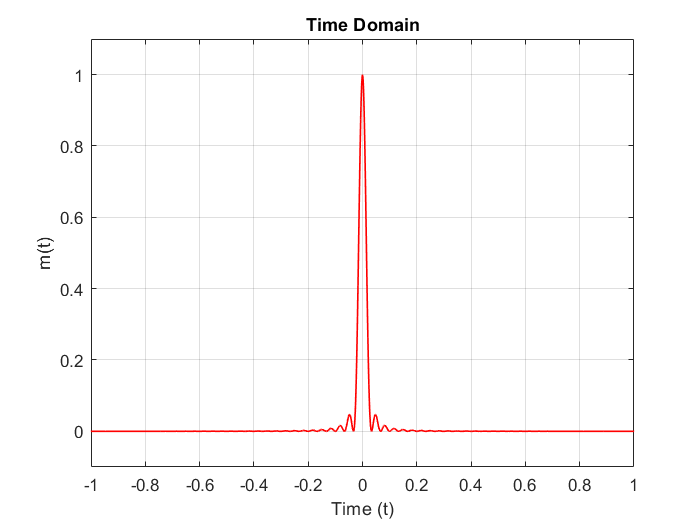

fs_part2 = 600;
ts_part2 = 1/fs_part2;
t_part2 = -5:ts_part2:5;
mt = sinc(30*t_part2).^2;
plot(t_part2, mt, 'r', 'linewidth', 1);
title('Time Domain');
xlabel('Time (t)');
ylabel('m(t)');
set(gca,'xtick', -1 : 0.2 : 1, 'xlim', [-1,1]);
set(gca,'ytick', 0 : 0.2 : 1.6, 'ylim', [-0.1,1.1]);
grid on;

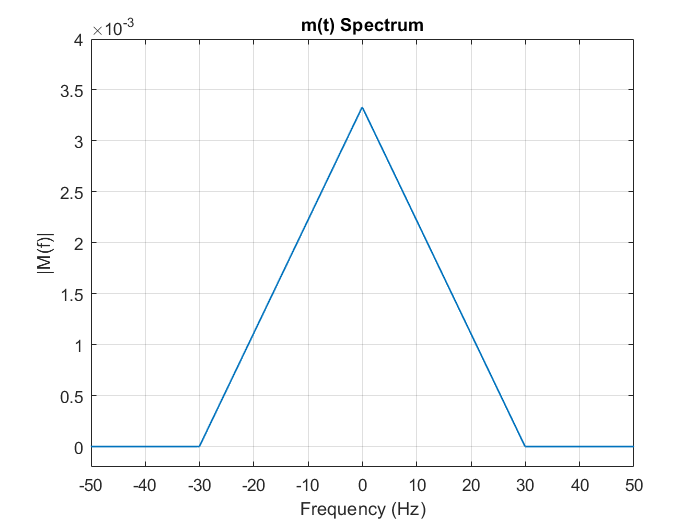


Mf = fftshift(fft(mt));
l_Mf = length(Mf);
abs_Mf = abs(Mf/l_Mf);
f1_part2 = -fs_part2/2 : fs_part2/l_Mf : fs_part2/2 - fs_part2/l_Mf;
plot(f1_part2, abs_Mf, 'linewidth', 1);
title('m(t) Spectrum');
xlabel('Frequency (Hz)');
ylabel('|M(f)|');
set(gca,'xtick', -50 : 10 : 50, 'xlim', [-50,50]);
set(gca,'ytick', -0.5*10^-3 : 0.5*10^-3 : 4*10^-3, 'ylim', [-0.2*10^-3,4*10^-3]);
grid on;

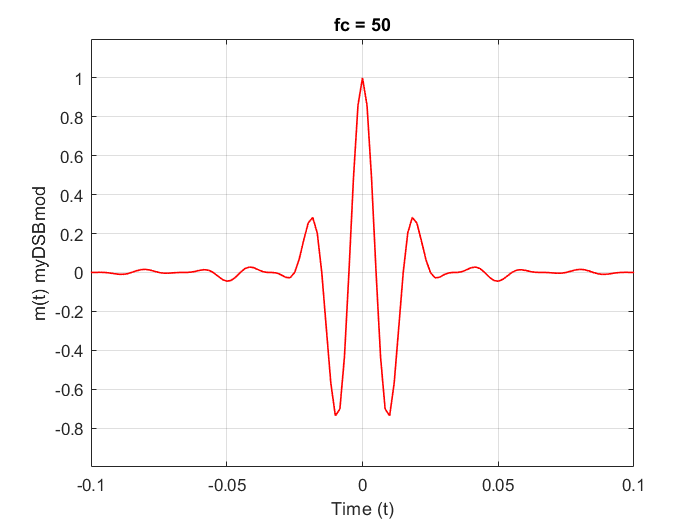


Ac_part2 = 1;
fc_part2 = 50;
mt_DSBmod = my_DSBmod(mt, Ac_part2, fc_part2, t_part2);
plot(t_part2, mt_DSBmod, 'r', 'linewidth', 1);
title('fc = 50');
xlabel('Time (t)');
ylabel('m(t) myDSBmod');
set(gca,'xtick', -0.2 : 0.05 : 0.2, 'xlim', [-0.1,0.1]);
set(gca,'ytick', -0.8 : 0.2 : 1, 'ylim', [-1,1.2]);
grid on;

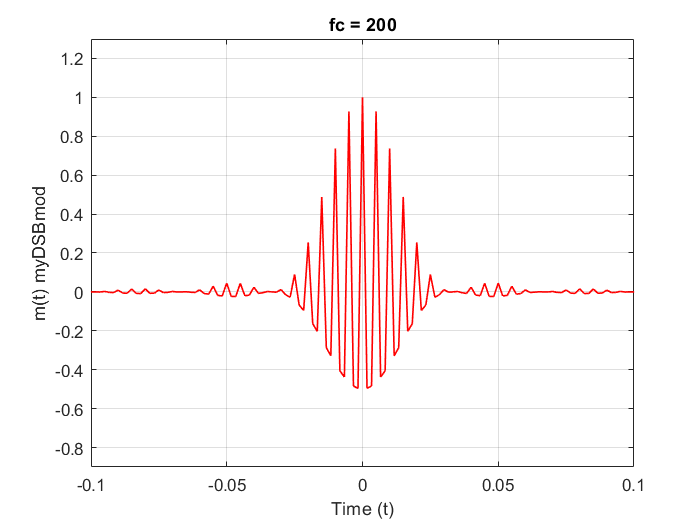


fc_part2 = 200;
mt_DSBmod = my_DSBmod(mt, Ac_part2, fc_part2, t_part2);
plot(t_part2, mt_DSBmod, 'r', 'linewidth', 1);
title('fc = 200');
xlabel('Time (t)');
ylabel('m(t) myDSBmod');
set(gca,'xtick', -0.2 : 0.05 : 0.2, 'xlim', [-0.1,0.1]);
set(gca,'ytick', -1.2 : 0.2 : 1.6, 'ylim', [-0.9,1.3]);
grid on;

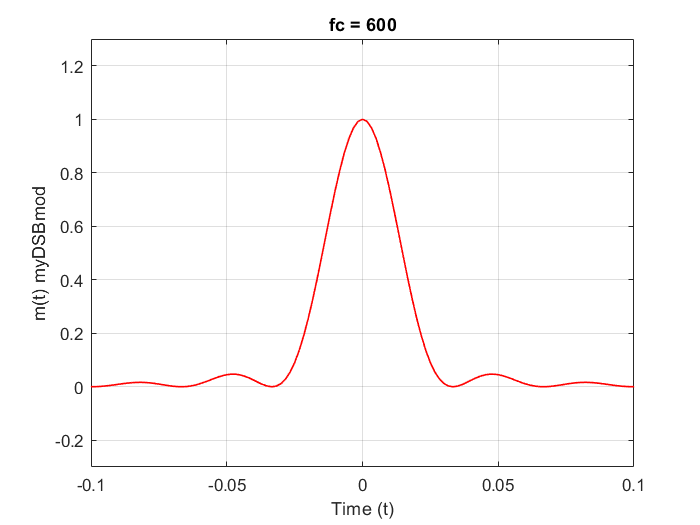


fc_part2 = 600;
mt_DSBmod = my_DSBmod(mt, Ac_part2, fc_part2, t_part2);
plot(t_part2, mt_DSBmod, 'r', 'linewidth', 1);
title('fc = 600');
xlabel('Time (t)');
ylabel('m(t) myDSBmod');
set(gca,'xtick', -0.2 : 0.05 : 0.2, 'xlim', [-0.1,0.1]);
set(gca,'ytick', -1.2 : 0.2 : 1.6, 'ylim', [-0.3,1.3]);
grid on;

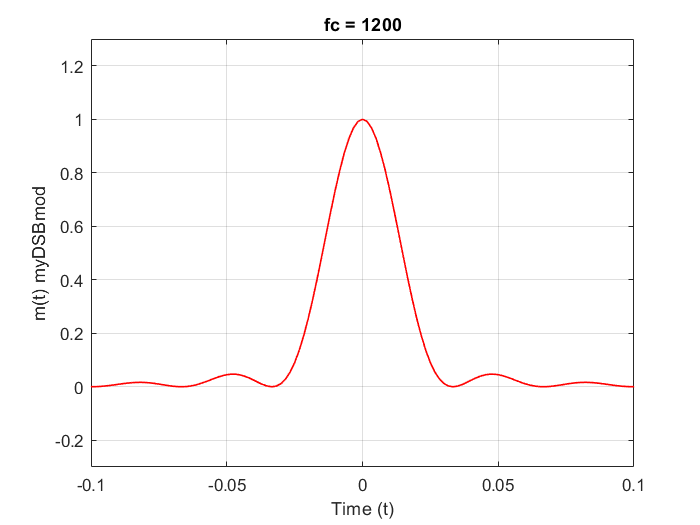


fc_part2 = 1200;
mt_DSBmod = my_DSBmod(mt, Ac_part2, fc_part2, t_part2);
plot(t_part2, mt_DSBmod, 'r', 'linewidth', 1);
title('fc = 1200');
xlabel('Time (t)');
ylabel('m(t) myDSBmod');
set(gca,'xtick', -0.2 : 0.05 : 0.2, 'xlim', [-0.1,0.1]);
set(gca,'ytick', -1.2 : 0.2 : 1.6, 'ylim', [-0.3,1.3]);
grid on;

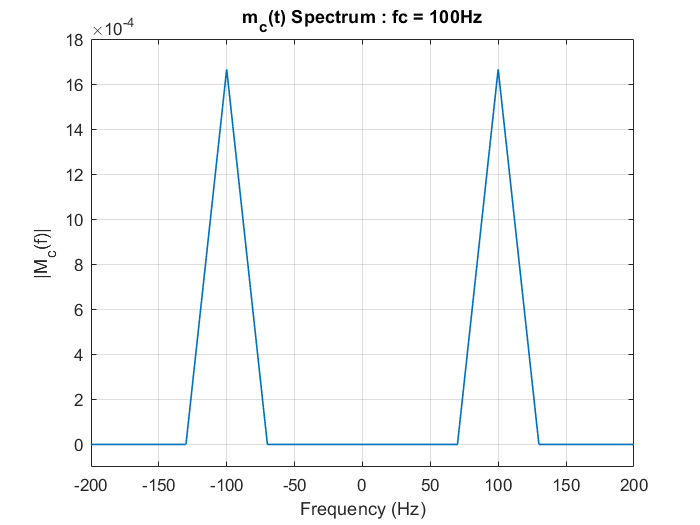


fc_part2 = 100;
mt_DSBmod = my_DSBmod(mt, Ac_part2, fc_part2, t_part2);
Mf_DSBmod = fftshift(fft(mt_DSBmod));
l_Mf_DSBmod = length(Mf_DSBmod);
abs_Mf_DSBmod = abs(Mf_DSBmod/l_Mf_DSBmod);
f2_part2 = -fs_part2/2 : fs_part2/l_Mf_DSBmod : fs_part2/2 - fs_part2/l_Mf_DSBmod;
plot(f2_part2, abs_Mf_DSBmod, 'linewidth', 1);
title('m_c(t) Spectrum : fc = 100Hz');
xlabel('Frequency (Hz)');
ylabel('|M_c(f)|');
set(gca,'xtick', -200 : 50 : 200, 'xlim', [-200,200]);
set(gca,'ytick', -0.2*10^-3 : 0.2*10^-3 : 2*10^-3, 'ylim', [-0.1*10^-3,1.8*10^-3]);
grid on;

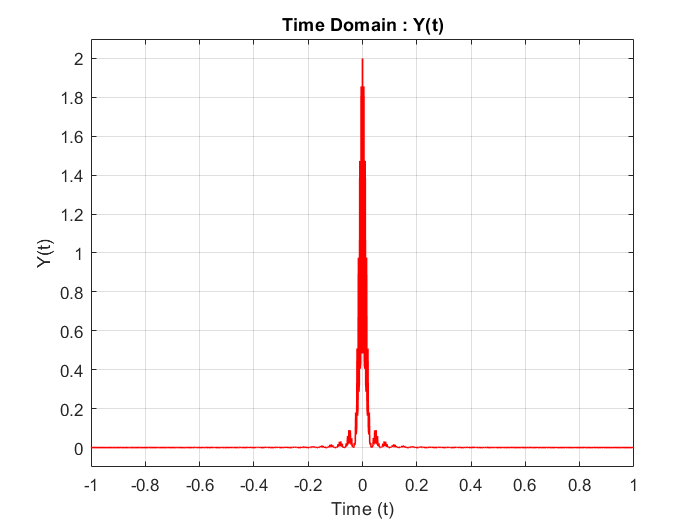


[Zt, Yt] = my_DSBdemod(mt_DSBmod, Ac_part2, fc_part2, t_part2);

plot(t_part2, Yt, 'r', 'linewidth', 1);
title('Time Domain : Y(t)');
xlabel('Time (t)');
ylabel('Y(t)');
set(gca,'xtick', -1 : 0.2 : 1, 'xlim', [-1,1]);
set(gca,'ytick', 0 : 0.2 : 2.6, 'ylim', [-0.1,2.1]);
grid on;

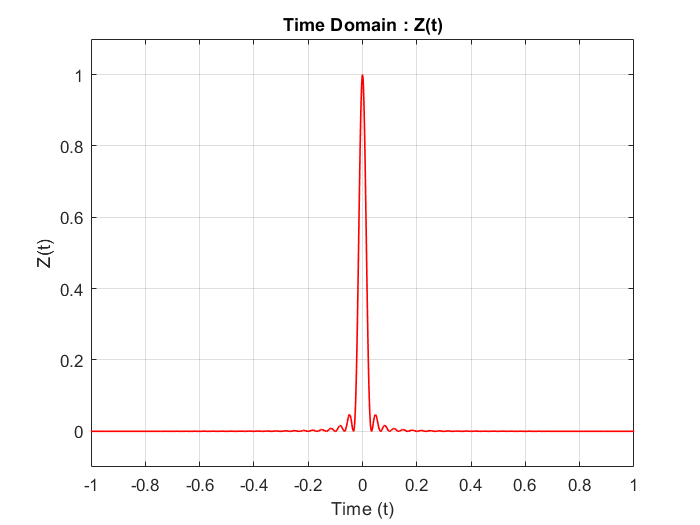


plot(t_part2, Zt, 'r', 'linewidth', 1);
title('Time Domain : Z(t)');
xlabel('Time (t)');
ylabel('Z(t)');
set(gca,'xtick', -1 : 0.2 : 1, 'xlim', [-1,1]);
set(gca,'ytick', 0 : 0.2 : 2.6, 'ylim', [-0.1,1.1]);
grid on;

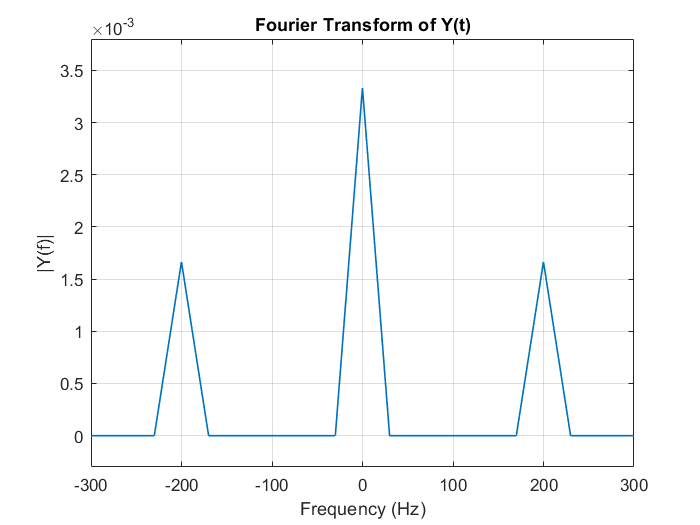


Yf = fftshift(fft(Yt));
l_Yf = length(Yf);
abs_Yf = abs(Yf/l_Yf);
f3_part2 = -fs_part2/2 : fs_part2/l_Yf : fs_part2/2 - fs_part2/l_Yf;
plot(f3_part2, abs_Yf, 'linewidth', 1);
title('Fourier Transform of Y(t)');
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');
set(gca,'xtick', -300 : 100 : 300, 'xlim', [-300,300]);
set(gca,'ytick', -0.5*10^-3 : 0.5*10^-3 : 3.5*10^-3, 'ylim', [-0.3*10^-3,3.8*10^-3]);
grid on;

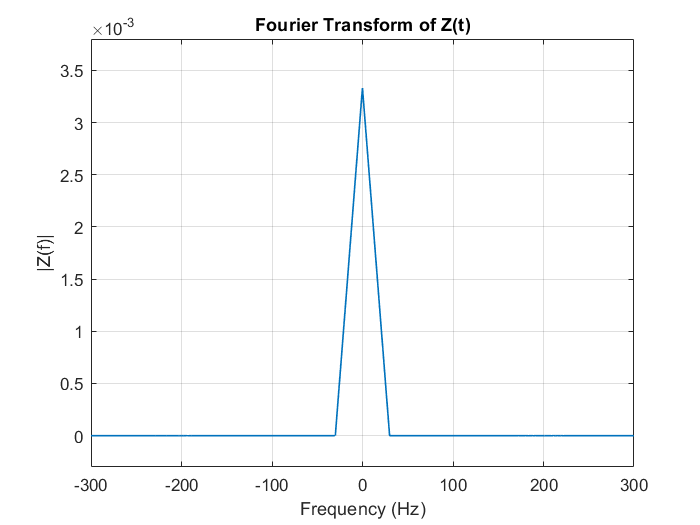


Zf = fftshift(fft(Zt));
l_Zf = length(Zf);
abs_Zf = abs(Zf/l_Zf);
f4_part2 = -fs_part2/2 : fs_part2/l_Zf : fs_part2/2 - fs_part2/l_Zf;
plot(f4_part2, abs_Zf, 'linewidth', 1);
title('Fourier Transform of Z(t)');
xlabel('Frequency (Hz)');
ylabel('|Z(f)|');
set(gca,'xtick', -300 : 100 : 300, 'xlim', [-300,300]);
set(gca,'ytick', -0.5*10^-3 : 0.5*10^-3 : 3.5*10^-3, 'ylim', [-0.3*10^-3,3.8*10^-3]);
grid on;

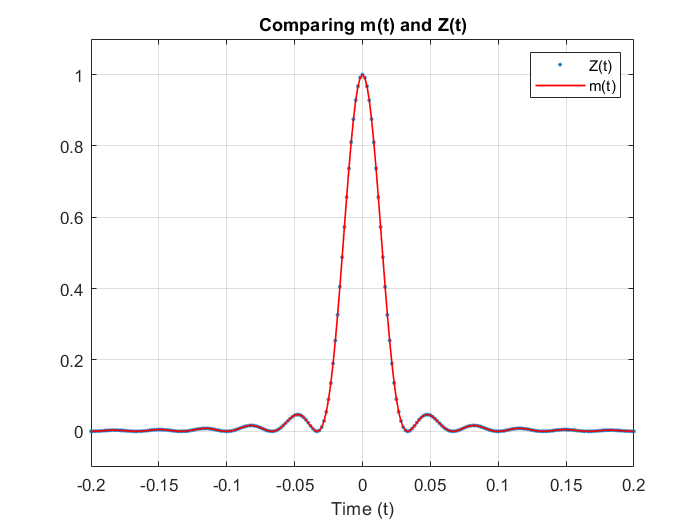


plot(t_part2, Zt,'.', t_part2, mt, 'r', 'linewidth', 1);
title('Comparing m(t) and Z(t)');
legend('Z(t)','m(t)');
xlabel('Time (t)');
set(gca,'xtick', -0.2 : 0.05 : 0.2, 'xlim', [-0.2,0.2]);
set(gca,'ytick', 0 : 0.2 : 2.6, 'ylim', [-0.1,1.1]);
grid on;


error_myDSBdemod = immse(mt,Zt)

error_myDSBdemod = 2.4959e-10

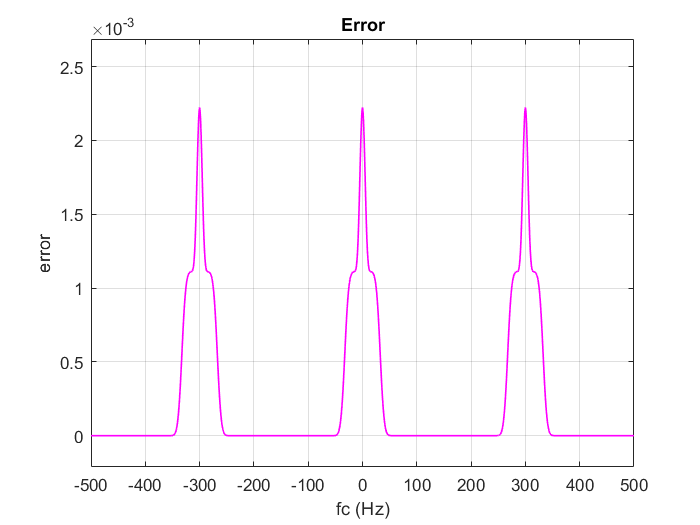


fcx_part2 = -500:500;
error = zeros(1, length(fcx_part2));
for fci = fcx_part2
    mti_DSBmod = my_DSBmod(mt, Ac_part2, fci, t_part2);
    [Zti, Yti] = my_DSBdemod(mti_DSBmod, Ac_part2, fci, t_part2);
    error(1, fci+501) = immse(mt,Zti);
end
plot(fcx_part2, error, 'm', 'linewidth', 1);
title('Error');
xlabel('fc (Hz)');
ylabel('error');
set(gca,'xtick', -500 : 100 : 500, 'xlim', [-500,500]);
set(gca,'ytick', -0.5*10^-3 : 0.5*10^-3 : 2.5*10^-3, 'ylim', [-0.2*10^-3,2.7*10^-3]);
grid on;

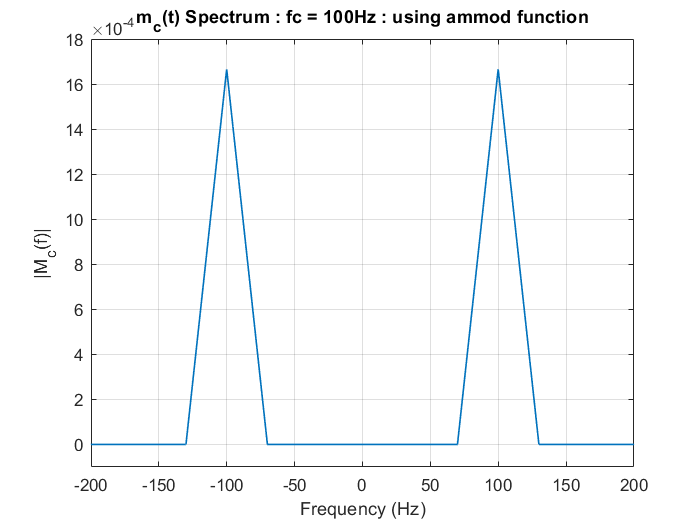


mt_ammod = ammod(mt,fc_part2,fs_part2);
Mf_ammod = fftshift(fft(mt_ammod));
l_Mf_ammod = length(Mf_ammod);
abs_Mf_ammod = abs(Mf_ammod/l_Mf_ammod);
f5_part2 = -fs_part2/2 : fs_part2/l_Mf_ammod : fs_part2/2 - fs_part2/l_Mf_ammod;
plot(f5_part2, abs_Mf_ammod, 'linewidth', 1);
title('m_c(t) Spectrum : fc = 100Hz : using ammod function');
xlabel('Frequency (Hz)');
ylabel('|M_c(f)|');
set(gca,'xtick', -200 : 50 : 200, 'xlim', [-200,200]);
set(gca,'ytick', -0.2*10^-3 : 0.2*10^-3 : 2*10^-3, 'ylim', [-0.1*10^-3,1.8*10^-3]);
grid on;

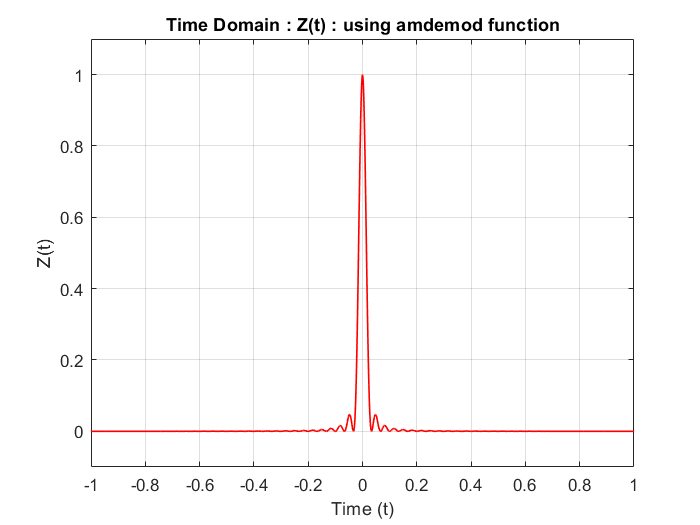


Zt_amdemod = amdemod(mt_ammod, fc_part2, fs_part2);
plot(t_part2, Zt_amdemod, 'r', 'linewidth', 1);
title('Time Domain : Z(t) : using amdemod function');
xlabel('Time (t)');
ylabel('Z(t)');
set(gca,'xtick', -1 : 0.2 : 1, 'xlim', [-1,1]);
set(gca,'ytick', 0 : 0.2 : 2.6, 'ylim', [-0.1,1.1]);
grid on;

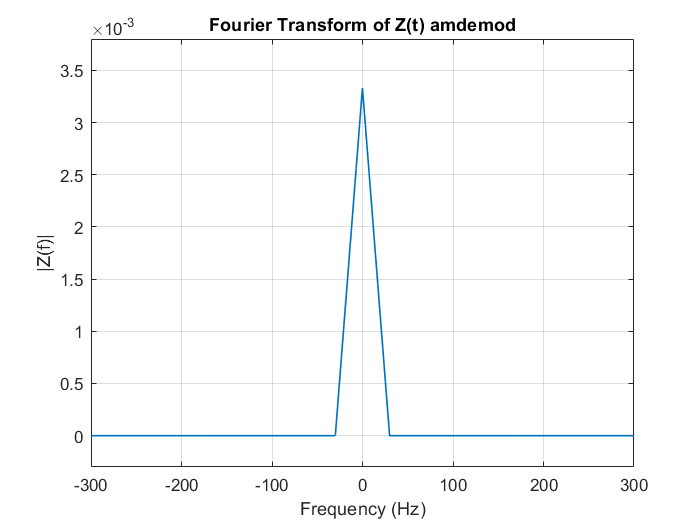


Zf_amdemod = fftshift(fft(Zt_amdemod));
l_Zf_amdemod = length(Zf_amdemod);
abs_Zf_amdemod = abs(Zf_amdemod/l_Zf_amdemod);
f6_part2 = -fs_part2/2 : fs_part2/l_Zf_amdemod : fs_part2/2 - fs_part2/l_Zf_amdemod;
plot(f6_part2, abs_Zf_amdemod, 'linewidth', 1);
title('Fourier Transform of Z(t) amdemod');
xlabel('Frequency (Hz)');
ylabel('|Z(f)|');
set(gca,'xtick', -300 : 100 : 300, 'xlim', [-300,300]);
set(gca,'ytick', -0.5*10^-3 : 0.5*10^-3 : 3.5*10^-3, 'ylim', [-0.3*10^-3,3.8*10^-3]);
grid on;

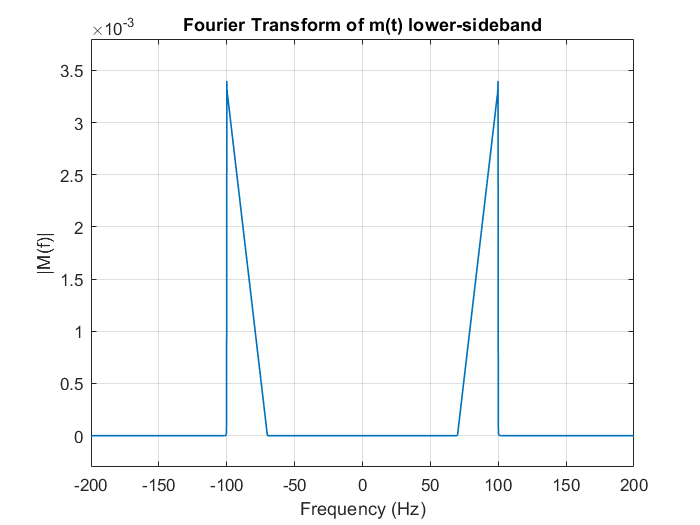


mt_ssbmod_lower = ssbmod(mt, fc_part2, fs_part2);
Mf_ssbmod_lower = fftshift(fft(mt_ssbmod_lower));
l_Mf_ssbmod_lower = length(Mf_ssbmod_lower);
abs_Mf_ssbmod_lower = abs(Mf_ssbmod_lower/l_Mf_ssbmod_lower);
f7_part2 = -fs_part2/2 : fs_part2/l_Mf_ssbmod_lower : fs_part2/2 - fs_part2/l_Mf_ssbmod_lower;
plot(f7_part2, abs_Mf_ssbmod_lower, 'linewidth', 1);
title('Fourier Transform of m(t) lower-sideband');
xlabel('Frequency (Hz)');
ylabel('|M(f)|');
set(gca,'xtick', -200 : 50 : 200, 'xlim', [-200,200]);
set(gca,'ytick', -0.5*10^-3 : 0.5*10^-3 : 3.5*10^-3, 'ylim', [-0.3*10^-3,3.8*10^-3]);
grid on;

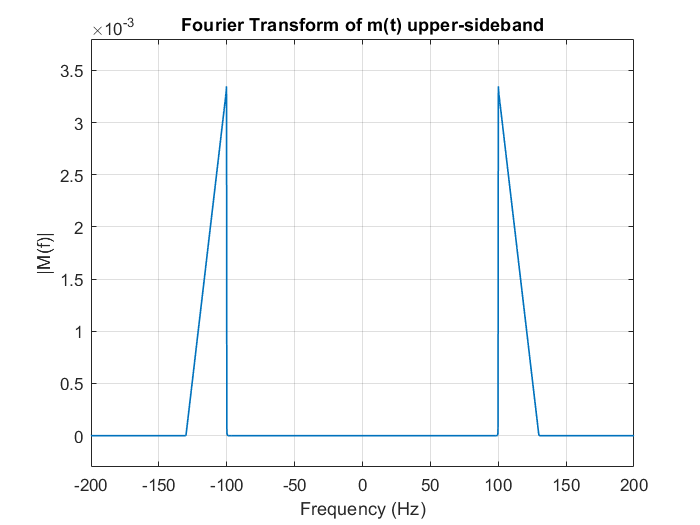


mt_ssbmod_upper = ssbmod(mt, fc_part2, fs_part2, 0, 'upper');
Mf_ssbmod_upper = fftshift(fft(mt_ssbmod_upper));
l_Mf_ssbmod_upper = length(Mf_ssbmod_upper);
abs_Mf_ssbmod_upper = abs(Mf_ssbmod_upper/l_Mf_ssbmod_upper);
f8_part2 = -fs_part2/2 : fs_part2/l_Mf_ssbmod_upper : fs_part2/2 - fs_part2/l_Mf_ssbmod_upper;
plot(f8_part2, abs_Mf_ssbmod_upper, 'linewidth', 1);
title('Fourier Transform of m(t) upper-sideband');
xlabel('Frequency (Hz)');
ylabel('|M(f)|');
set(gca,'xtick', -200 : 50 : 200, 'xlim', [-200,200]);
set(gca,'ytick', -0.5*10^-3 : 0.5*10^-3 : 3.5*10^-3, 'ylim', [-0.3*10^-3,3.8*10^-3]);
grid on;

# **% Part 3:**

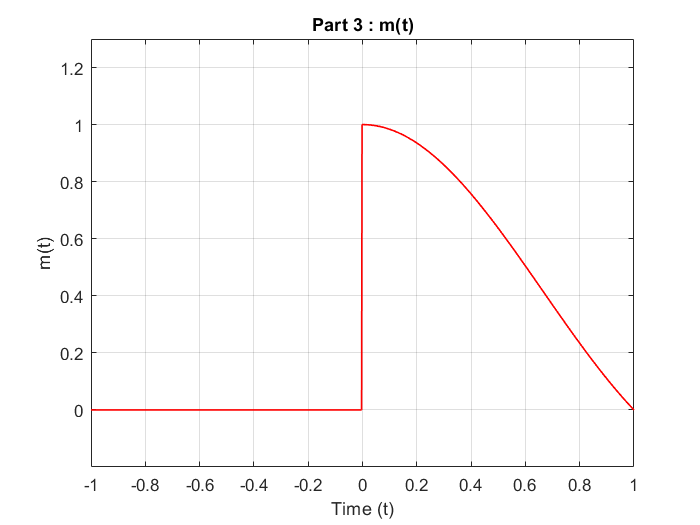

fs_part3 = 600;
ts_part3 = 1/fs_part3;
t_part3 = -1:ts_part3:1;
mt_part3 = sinc(t_part3);
mt_part3(1, 1: fs_part3 - 1) = 0;

hmt_part3 = hilbert(mt_part3);
% plot(t_part3, real(hmt_part3), t_part3, imag(hmt_part3), 'r', 'linewidth', 1);
% legend('real','imaginary');
% title('hilbert Function');
% xlabel('Time (s)');

plot(t_part3,mt_part3, 'r', 'linewidth', 1);
title('Part 3 : m(t)');
xlabel('Time (t)');
ylabel('m(t)');
set(gca,'xtick', -1 : 0.2 : 1, 'xlim', [-1,1]);
set(gca,'ytick', 0 : 0.2 : 1.6, 'ylim', [-0.2,1.3]);
grid on;

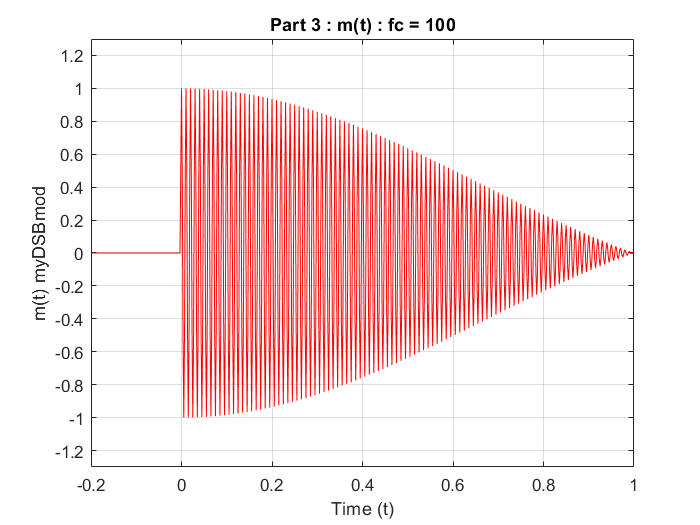


Ac_part3 = 1;
fc_part3 = 100;
mt_part3_DSBmod = my_DSBmod(mt_part3, Ac_part3, fc_part3, t_part3);
plot(t_part3,mt_part3_DSBmod, 'r');
title('Part 3 : m(t) : fc = 100');
xlabel('Time (t)');
ylabel('m(t) myDSBmod');
set(gca,'xtick', -1 : 0.2 : 1, 'xlim', [-0.2,1]);
set(gca,'ytick', -1.2 : 0.2 : 1.6, 'ylim', [-1.3,1.3]);
grid on;

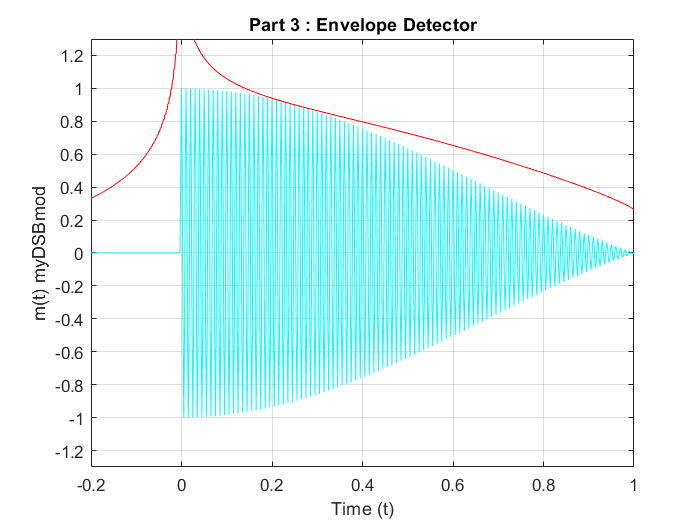


plot(t_part3,mt_part3_DSBmod,'c',t_part3,abs(hmt_part3),'r');
title('Part 3 : Envelope Detector');
xlabel('Time (t)');
ylabel('m(t) myDSBmod');
set(gca,'xtick', -1 : 0.2 : 1, 'xlim', [-0.2,1]);
set(gca,'ytick', -1.2 : 0.2 : 1.6, 'ylim', [-1.3,1.3]);
grid on;

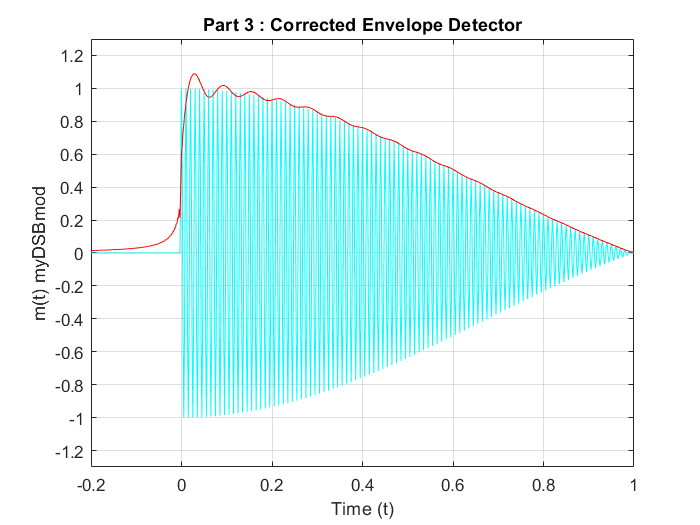


hmt_part3_corrected = hilbert(mt_part3.*sin(fc_part3*t_part3));
plot(t_part3,mt_part3_DSBmod,'c',t_part3,abs(hmt_part3_corrected),'r');
title('Part 3 : Corrected Envelope Detector');
xlabel('Time (t)');
ylabel('m(t) myDSBmod');
set(gca,'xtick', -1 : 0.2 : 1, 'xlim', [-0.2,1]);
set(gca,'ytick', -1.2 : 0.2 : 1.6, 'ylim', [-1.3,1.3]);
grid on;

# **% My Functions:**

function Xc = my_AMmod(x, Ac, mu, fc, t)
    n = max(abs(x));
    Xc = Ac*(1 + mu*x/n).*cos(2*pi*fc*t);
end
% =-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=
function Xc = my_DSBmod(x, Ac, fc, t)
    Xc = Ac*x.*cos(2*pi*fc*t);
end
% =-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=
function [Zt, Yt] = my_DSBdemod(Xc, Ac, fc, t)
    Yt = 2*Ac*Xc.*cos(2*pi*fc*t);
    Zt = lowpass(Yt,50,600);
end